% ========================================================
% === SCRIPT COMPLETO: PIPELINE SVD_BC + GCN SU VOLTI   ===
% ========================================================
clear; clc; close all;
rng(0);

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/1 anno 2023-2024/1 Semestre 2023-2024/Metodi Numerici Avanzati/ProgettoMetodi';
addpath(genpath(projectRoot));              % tutte le subfolder

this_folder  = pwd;
results_path = fullfile(this_folder, 'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI GLOBALI SVD_BC
%% ----------------------------------------------------------------
tol   = 1e-4;
maxit = 1000;
energy_threshold = 0.95;   % mantieni il 95% dell’energia

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL & MEAN FACE
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');   t = tic;

>>> Caricamento dataset ORL...


load('dataset/volti_dataset.mat');           % A (m×n), labels
A = double(A) / 255;
labels = labels(:);
fprintf('   fatto in %.2f s\n', toc(t));

   fatto in 0.04 s



[m, n] = size(A);
img_h = 112;  img_w = 92;
num_classes = max(labels);

fprintf('>>> Calcolo volto medio...\n');      t = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t));

   ok in 0.01 s



fprintf('>>> Centratura dati...\n');           t = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t));

   ok in 0.00 s



%% ----------------------------------------------------------------
%% 3) SVD_BC su dati centrati
%% ----------------------------------------------------------------
fprintf('>>> Lancio svd_BC (tol=%.1e,maxit=%d)...\n', tol, maxit);

>>> Lancio svd_BC (tol=1.0e-04,maxit=1000)...


t = tic;
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 410x410 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=410 ... 

iter=1001 time=8.54 s
         [qr_eig] deflazione k=409 ... 

iter=1001 time=9.07 s
         [qr_eig] deflazione k=408 ... 

iter=1001 time=8.76 s
         [qr_eig] deflazione k=407 ... 

iter=1001 time=8.68 s
         [qr_eig] deflazione k=406 ... 

iter=1001 time=8.69 s
         [qr_eig] deflazione k=405 ... 

iter=1001 time=8.65 s
         [qr_eig] deflazione k=404 ... iter=611 time=5.35 s
         [qr_eig] deflazione k=403 ... 

iter=1001 time=8.74 s
         [qr_eig] deflazione k=402 ... 

iter=1001 time=9.45 s
         [qr_eig] deflazione k=401 ... 

iter=1001 time=8.65 s
         [qr_eig] deflazione k=400 ... 

iter=1001 time=8.64 s
         [qr_eig] deflazione k=399 ... 

iter=1001 time=8.46 s
         [qr_eig] deflazione k=398 ... 

iter=1001 time=8.40 s
         [qr_eig] deflazione k=397 ... 

iter=1001 time=8.49 s
         [qr_eig] deflazione k=396 ... 

iter=1001 time=8.24 s
         [qr_eig] deflazione k=395 ... 

iter=1001 time=8.47 s
         [qr_eig] deflazione k=394 ... 

iter=1001 time=8.33 s
         [qr_eig] deflazione k=393 ... 

iter=1001 time=8.33 s
         [qr_eig] deflazione k=392 ... 

iter=1001 time=8.23 s
         [qr_eig] deflazione k=391 ... 

iter=1001 time=8.06 s
         [qr_eig] deflazione k=390 ... 

iter=1001 time=8.09 s
         [qr_eig] deflazione k=389 ... 

iter=1001 time=8.36 s
         [qr_eig] deflazione k=388 ... 

iter=1001 time=7.92 s
         [qr_eig] deflazione k=387 ... 

iter=1001 time=7.94 s
         [qr_eig] deflazione k=386 ... iter=407 time=3.28 s
         [qr_eig] deflazione k=385 ... 

iter=1001 time=7.81 s
         [qr_eig] deflazione k=384 ... 

iter=1001 time=7.73 s
         [qr_eig] deflazione k=383 ... 

iter=1001 time=7.66 s
         [qr_eig] deflazione k=382 ... 

iter=1001 time=7.66 s
         [qr_eig] deflazione k=381 ... 

iter=1001 time=7.85 s
         [qr_eig] deflazione k=380 ... 

iter=1001 time=7.73 s
         [qr_eig] deflazione k=379 ... 

iter=1001 time=7.89 s
         [qr_eig] deflazione k=378 ... iter=136 time=1.08 s
         [qr_eig] deflazione k=377 ... 

iter=1001 time=7.63 s
         [qr_eig] deflazione k=376 ... 

iter=1001 time=7.67 s
         [qr_eig] deflazione k=375 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=374 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=373 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=372 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=371 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=370 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=369 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=368 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=367 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=366 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=365 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=364 ... 

iter=1001 time=7.15 s
         [qr_eig] deflazione k=363 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=362 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=361 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=360 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=359 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=358 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=357 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=356 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=355 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=354 ... iter=478 time=3.22 s
         [qr_eig] deflazione k=353 ... 

iter=1001 time=6.93 s
         [qr_eig] deflazione k=352 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=351 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=350 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=349 ... 

iter=1001 time=6.59 s
         [qr_eig] deflazione k=348 ... 

iter=1001 time=6.52 s
         [qr_eig] deflazione k=347 ... 

iter=1001 time=6.58 s
         [qr_eig] deflazione k=346 ... 

iter=1001 time=6.47 s
         [qr_eig] deflazione k=345 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=344 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=343 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=342 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=341 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=340 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=339 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=338 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=337 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=336 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=335 ... 

iter=1001 time=6.15 s
         [qr_eig] deflazione k=334 ... 

iter=1001 time=6.11 s
         [qr_eig] deflazione k=333 ... iter=39 time=0.24 s
         [qr_eig] deflazione k=332 ... 

iter=1001 time=6.07 s
         [qr_eig] deflazione k=331 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=330 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=329 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=328 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=327 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=326 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=325 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=324 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=323 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=322 ... 

iter=1001 time=5.72 s
         [qr_eig] deflazione k=321 ... 

iter=1001 time=7.69 s
         [qr_eig] deflazione k=320 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=319 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=318 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=317 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=316 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=315 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=314 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=313 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=312 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=311 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=310 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=309 ... 

iter=1001 time=5.41 s
         [qr_eig] deflazione k=308 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=307 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=306 ... iter=170 time=0.92 s
         [qr_eig] deflazione k=305 ... iter=222 time=1.16 s
         [qr_eig] deflazione k=304 ... iter=901 time=4.74 s
         [qr_eig] deflazione k=303 ... 

iter=1001 time=5.20 s
         [qr_eig] deflazione k=302 ... iter=11 time=0.07 s
         [qr_eig] deflazione k=301 ... 

iter=1001 time=5.08 s
         [qr_eig] deflazione k=300 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=299 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=298 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=297 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=296 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=295 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=294 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=293 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=292 ... iter=326 time=1.61 s
         [qr_eig] deflazione k=291 ... 

iter=1001 time=5.16 s
         [qr_eig] deflazione k=290 ... 

iter=1001 time=4.74 s
         [qr_eig] deflazione k=289 ... 

iter=1001 time=5.12 s
         [qr_eig] deflazione k=288 ... 

iter=1001 time=4.60 s
         [qr_eig] deflazione k=287 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=286 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=285 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=284 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=283 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=282 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=281 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=280 ... 

iter=1001 time=4.44 s
         [qr_eig] deflazione k=279 ... 

iter=1001 time=4.51 s
         [qr_eig] deflazione k=278 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=277 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=276 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=275 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=274 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=273 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=272 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=271 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=270 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=269 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=268 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=267 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=266 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=265 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=264 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=263 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=262 ... iter=0 time

iter=1001 time=3.93 s
         [qr_eig] deflazione k=259 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=258 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=257 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=256 ... 

iter=1001 time=3.71 s
         [qr_eig] deflazione k=255 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=254 ... 

iter=1001 time=4.83 s
         [qr_eig] deflazione k=253 ... iter=312 time=1.60 s
         [qr_eig] deflazione k=252 ... iter=626 time=3.00 s
         [qr_eig] deflazione k=251 ... 

iter=1001 time=5.45 s
         [qr_eig] deflazione k=250 ... 

iter=1001 time=4.20 s
         [qr_eig] deflazione k=249 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=248 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=247 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=246 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=245 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=244 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=243 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=242 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=241 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=240 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=239 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=238 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=237 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=236 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=235 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=234 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=233 ... 

iter=1001 time=3.48 s
         [qr_eig] deflazione k=232 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=231 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=230 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=229 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=228 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=227 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=226 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=225 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=224 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=223 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=222 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=221 ... 

iter=1001 time=3.02 s
         [qr_eig] deflazione k=220 ... 

iter=1001 time=2.96 s
         [qr_eig] deflazione k=219 ... 

iter=1001 time=3.02 s
         [qr_eig] deflazione k=218 ... 

iter=1001 time=2.93 s
         [qr_eig] deflazione k=217 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=216 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=215 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=214 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=213 ... iter=561 time=1.67 s
         [qr_eig] deflazione k=212 ... 

iter=1001 time=2.76 s
         [qr_eig] deflazione k=211 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=210 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=209 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=208 ... 

iter=1001 time=2.67 s
         [qr_eig] deflazione k=207 ... 

iter=1001 time=2.72 s
         [qr_eig] deflazione k=206 ... 

iter=1001 time=2.62 s
         [qr_eig] deflazione k=205 ... 

iter=1001 time=2.64 s
         [qr_eig] deflazione k=204 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=203 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=202 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=201 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=200 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=199 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=198 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=197 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=196 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=195 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=194 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=193 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=192 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=191 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=190 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=189 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=188 ... iter=0 time

iter=1001 time=2.11 s
         [qr_eig] deflazione k=173 ... iter=760 time=1.55 s
         [qr_eig] deflazione k=172 ... 

iter=1001 time=2.06 s
         [qr_eig] deflazione k=171 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=170 ... 

iter=1001 time=2.07 s
         [qr_eig] deflazione k=169 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=168 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=167 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=166 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=165 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=164 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=163 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=162 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=161 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=160 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=159 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=158 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=157 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=156 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=155 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=154 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=153 ... iter=0 time

iter=1001 time=0.24 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... 

iter=1001 time=0.19 s
         [qr_eig] deflazione k=48 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=47 ... iter=3 time=0.00 s
         [qr_eig] deflazione k=46 ... iter=35 time=0.01 s
         [qr_eig] deflazione k=45 ... 

iter=1001 time=0.17 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=41 ... iter=1 time=0.00 s
         [qr_eig] deflazione k=40 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=29 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=28 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=27 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=26 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=25 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=24 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=23 ... iter=0 time=0.00 s
         

iter=1001 time=0.02 s
         [qr_eig] deflazione k=9 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=8 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=7 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=6 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=5 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=4 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=3 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=2 ... iter=0 time=0.00 s
      [qr_eig] tutti autovalori estratti.
   [svd_BC] qr_eig completata in 469.21 s
   [svd_BC] costruisco S e U...


fprintf('   completata in %.2f s\n', toc(t));

   completata in 469.36 s


save(fullfile(results_path,'svd_data.mat'),'U','S','V');

%% ----------------------------------------------------------------
%% 4) Selezione di k da energia cumulata
%% ----------------------------------------------------------------
eigvals = diag(S);
energy  = cumsum(eigvals) / sum(eigvals);
k = find(energy > energy_threshold, 1);
fprintf('>>> Uso k = %d componenti (%.1f%% energia)\n', k, 100*energy(k));

>>> Uso k = 400 componenti (95.3% energia)



%% ----------------------------------------------------------------
%% 5) Calcolo proiezioni PCA [n_samples×k]
%% ----------------------------------------------------------------
U_k         = U(:,1:k);
projections = (U_k' * A_centered)';   % [n×k]

%% ----------------------------------------------------------------
%% 6) Visualizzazione mean & prime eigenfaces
%% ----------------------------------------------------------------
fprintf('>>> Visualizzazione SVD results...\n');

>>> Visualizzazione SVD results...


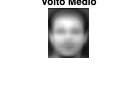


figure('Name','Volto Medio','NumberTitle','off');
imshow(reshape(mean_face,img_h,img_w),[]);
title('Volto Medio');
saveas(gcf, fullfile(results_path,'volto_medio.png'));

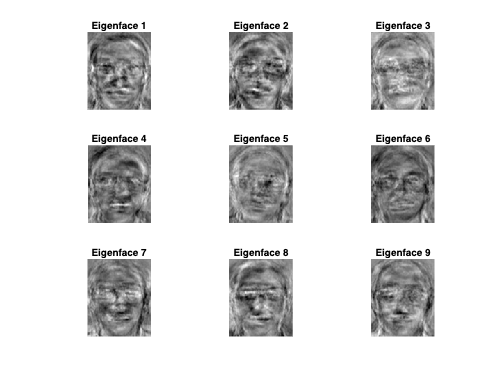


figure('Name','Eigenfaces','NumberTitle','off');
for i = 1:9
    subplot(3,3,i);
    imshow(reshape(U(:,i),img_h,img_w),[]);
    title(sprintf('Eigenface %d',i));
end
saveas(gcf, fullfile(results_path,'eigenfaces.png'));


%% ----------------------------------------------------------------
%% 7) PREPARAZIONE FEATURE E ONE‐HOT
%% ----------------------------------------------------------------
X = projections;                      % [n_samples×k]
num_samples = size(X,1);
Y = zeros(num_classes, num_samples);
for i = 1:num_samples
    Y(labels(i), i) = 1;
end

%% ----------------------------------------------------------------
%% 8) COSTRUZIONE DEL GRAFO DI SIMILARITÀ
%% ----------------------------------------------------------------
K = 10;   % numero di vicini per nodo
A_graph = zeros(num_samples);
for i = 1:num_samples
    dists = sum((X - X(i,:)).^2, 2);
    [~, idx] = sort(dists);
    nbrs = idx(2:K+1);
    A_graph(i, nbrs) = 1;
end
A_graph = max(A_graph, A_graph');     % simmetrico
A_hat   = A_graph + eye(num_samples);

D       = diag(sum(A_hat,2));
A_hat_norm = D^(-0.5) * A_hat * D^(-0.5);

%% ----------------------------------------------------------------
%% 9) SPLIT TRAIN/TEST
%% ----------------------------------------------------------------
rng(0);
perm  = randperm(num_samples);
split = round(0.8 * num_samples);
train_idx = perm(1:split);
test_idx  = perm(split+1:end);

X_train = X(train_idx,:);
Y_train = Y(:,train_idx);
X_test  = X(test_idx,:);
Y_test  = Y(:,test_idx);

A_train = A_hat_norm(train_idx,train_idx);
A_test  = A_hat_norm(test_idx, train_idx);

%% ----------------------------------------------------------------
%% 10) TRAINING GCN
%% ----------------------------------------------------------------
epochs        = 100;
learning_rate = 0.01;
fprintf('>>> Training GCN...\n');

>>> Training GCN...


[W, loss_hist] = gcn_train(X_train, Y_train, A_train, epochs, learning_rate);

[GCN] Epoch  10/100 - Loss: 3.0887
[GCN] Epoch  20/100 - Loss: 2.0529
[GCN] Epoch  30/100 - Loss: 1.6141
[GCN] Epoch  40/100 - Loss: 1.3836
[GCN] Epoch  50/100 - Loss: 1.2323
[GCN] Epoch  60/100 - Loss: 1.1204
[GCN] Epoch  70/100 - Loss: 1.0328
[GCN] Epoch  80/100 - Loss: 0.9618
[GCN] Epoch  90/100 - Loss: 0.9027
[GCN] Epoch 100/100 - Loss: 0.8527



%% ----------------------------------------------------------------
%% 11) VALUTAZIONE SU TEST SET
%% ----------------------------------------------------------------
Z_test = (A_test * X_train) * W;  % [n_test×num_classes]
Z_test = Z_test';
Z_test = Z_test - max(Z_test,[],1);
expZ   = exp(Z_test);
A2     = expZ ./ sum(expZ,1);
[~, y_pred] = max(A2,[],1);
[~, y_true] = max(Y(:,test_idx),[],1);

acc = mean(y_pred' == y_true');
fprintf('>>> Test accuracy (GCN): %.2f%%\n', acc*100);

>>> Test accuracy (GCN): 75.61%


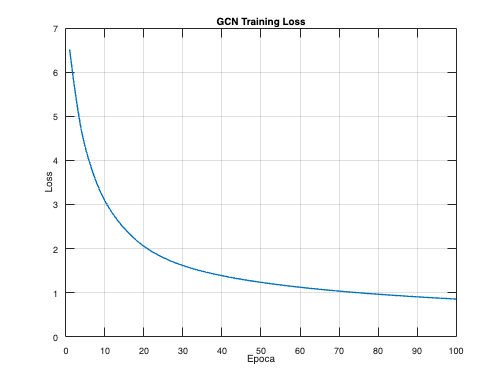


%% ----------------------------------------------------------------
%% 12) VISUALIZZAZIONE LOSS
%% ----------------------------------------------------------------
figure;
plot(1:epochs, loss_hist, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss');
title('GCN Training Loss');
grid on;
saveas(gcf, fullfile(results_path,'gcn_loss.png'));


fprintf('>>> Fine script (totale %.2f s)\n', toc);

>>> Fine script (totale 6112.87 s)
